Brief summary of this function.

Detailed explanation of this function.

SNRS = [0,40,80,Inf];
iters = 100;

%% initialized exp_data %%
init_SNR_iters = [];
rnd_SNR_iters = [];
exp_data.iterations = [];
exp_data.type = [];
exp_data.SNR = ones(1,iters*2)*SNRS(1);
exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*SNRS(2)];
exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*SNRS(3)];
exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*SNRS(4)];
options = struct;
options.TolFun = eps^2;
options.TolX = eps;
options.LargeScale = false;
%% -----------------   %%
for SNR=1:size(SNRS,2)
    init_iterations = [];
    rnd_iterations = [];
    for iter=1:iters
        dim = [20,20,20];
        T = zeros(dim);
        for i = 1:dim(1)
            T(i,:,:) = circulant(randi([-100,100],size(T,2),1),-1);
        end

        x = randi([-100,100],size(T,2),1);
    
        b = tmprod(T,{x.',x.'},[2,3]);
        b_noisy = noisy(b,SNRS(SNR));
        T_noisy = noisy(T,SNRS(SNR));
        T_noisy_dup  = T_noisy;


        F = 1/sqrt(dim(2))*dftmtx(dim(2));
        F_list = {F,F};
        omega = tmprod(T_noisy_dup,F_list,[2,3]);
        T_noisy_dup = zeros(size(omega));

        for k = 1:size(T,1)
            T_noisy_dup(k,:,:) = diag(diag(squeeze(omega(k,:,:))));
        end

        y = solve_part_diag(T_noisy_dup,b);
        xest = conj(F)\y;   

        best = tmprod(T_noisy,{xest.',xest.'},[2,3]);
        rerrb = frob(b-best)/frob(b)
     
        U0 = {xest,xest};
        [U,output] = lscpd_nls(T_noisy,b,U0,options);
        output.iterations
        init_iterations = [init_iterations,output.iterations];

        %%collecting data
        exp_data.iterations = [exp_data.iterations,output.iterations];
        exp_data.type = [exp_data.type,1];
        %%--------------%%

        U0 = cpd_rnd(dim(2:3),1);
        [U2,output2] = lscpd_nls(T_noisy,b,U0,options);

        %%collecting data
        rnd_iterations= [rnd_iterations,output2.iterations];
        exp_data.iterations = [exp_data.iterations,output2.iterations];
        exp_data.type = [exp_data.type,0];
        %%--------------%%
    end
    init_SNR_iters = [init_SNR_iters;init_iterations];
    rnd_SNR_iters = [rnd_SNR_iters;rnd_iterations];
end

rerrb = 8.9282

ans = 7

rerrb = 0.9142

ans = 8

rerrb = 1.2765

ans = 8

rerrb = 1.7371

ans = 8

rerrb = 85.0088

ans = 8

rerrb = 1.0341

ans = 7

rerrb = 2.9204

ans = 9

rerrb = 2.8897

ans = 7

rerrb = 9.5405

ans = 8

rerrb = 2.5113

ans = 8

rerrb = 2.2669

ans = 8

rerrb = 1.7142

ans = 9

rerrb = 1.5980

ans = 8

rerrb = 1.0957

ans = 7

rerrb = 0.9989

ans = 8

rerrb = 3.0240

ans = 8

rerrb = 1.8158e+03

ans = 7

rerrb = 16.8738

ans = 8

rerrb = 0.8709

ans = 11

rerrb = 1.0194

ans = 8

rerrb = 1.0061

ans = 9

rerrb = 1.1032

ans = 9

rerrb = 1.0630

ans = 8

rerrb = 0.9007

ans = 9

rerrb = 0.8192

ans = 9

rerrb = 1.3381

ans = 7

rerrb = 0.9026

ans = 10

rerrb = 1.6788

ans = 10

rerrb = 1.3299

ans = 9

rerrb = 2.7160

ans = 8

rerrb = 9.4631

ans = 7

rerrb = 1.3612

ans = 8

rerrb = 1.4967

ans = 9

rerrb = 107.1043

ans = 7

rerrb = 0.6956

ans = 9

rerrb = 3.1008

ans = 9

rerrb = 0.9282

ans = 8

rerrb = 3.5046

ans = 9

rerrb = 5.0997

ans = 7

rerrb = 1.7360

ans = 7

rerrb = 1.0268

ans = 8

rerrb = 12.7914

ans = 8

rerrb = 0.9348

ans = 9

rerrb = 18.7438

ans = 8

rerrb = 2.7405

ans = 6

rerrb = 0.8892

ans = 8

rerrb = 2.1657

ans = 8

rerrb = 3.5752

ans = 7

rerrb = 1.7174

ans = 7

rerrb = 10.5882

ans = 7

rerrb = 1.2736

ans = 7

rerrb = 0.6635

ans = 10

rerrb = 0.7561

ans = 8

rerrb = 2.3212

ans = 6

rerrb = 1.6736

ans = 8

rerrb = 1.4034

ans = 9

rerrb = 0.6498

ans = 11

rerrb = 2.5824

ans = 8

rerrb = 1.0382

ans = 8

rerrb = 5.1838

ans = 8

rerrb = 6.2065

ans = 9

rerrb = 1.2986

ans = 10

rerrb = 1.0127

ans = 9

rerrb = 1.0487

ans = 8

rerrb = 1.0989

ans = 9

rerrb = 6.0569

ans = 7

rerrb = 3.4876

ans = 7

rerrb = 1.9587

ans = 8

rerrb = 2.1688

ans = 8

rerrb = 1.1600

ans = 9

rerrb = 1.2291

ans = 7

rerrb = 16.5332

ans = 9

rerrb = 1.8469

ans = 9

rerrb = 1.8885

ans = 8

rerrb = 1.2237

ans = 7

rerrb = 1.2584

ans = 7

rerrb = 0.8954

ans = 7

rerrb = 0.6959

ans = 9

rerrb = 0.7686

ans = 7

rerrb = 0.6645

ans = 7

rerrb = 2.0914

ans = 8

rerrb = 2.3713

ans = 8

rerrb = 1.0064

ans = 9

rerrb = 1.1175

ans = 8

rerrb = 0.8968

ans = 8

rerrb = 2.5899

ans = 8

rerrb = 2.4620

ans = 7

rerrb = 0.8350

ans = 8

rerrb = 1.1774

ans = 9

rerrb = 1.1850

ans = 9

rerrb = 1.4334

ans = 8

rerrb = 43.3820

ans = 7

rerrb = 1.9042

ans = 7

rerrb = 22.8391

ans = 8

rerrb = 3.8891

ans = 8

rerrb = 17.4732

ans = 7

rerrb = 0.6508

ans = 9

rerrb = 1.5612

ans = 8

rerrb = 0.8654

ans = 10

rerrb = 1.5996

ans = 9

rerrb = 0.0067

ans = 7

rerrb = 0.0074

ans = 6

rerrb = 0.0057

ans = 8

rerrb = 0.0055

ans = 8

rerrb = 0.0068

ans = 14

rerrb = 0.0103

ans = 14

rerrb = 0.0057

ans = 6

rerrb = 0.0075

ans = 6

rerrb = 0.0052

ans = 10

rerrb = 0.0092

ans = 5

rerrb = 0.0105

ans = 8

rerrb = 0.0068

ans = 8

rerrb = 0.0073

ans = 10

rerrb = 0.0073

ans = 7

rerrb = 0.0091

ans = 8

rerrb = 0.0084

ans = 8

rerrb = 0.0087

ans = 7

rerrb = 0.0068

ans = 6

rerrb = 0.0084

ans = 8

rerrb = 0.0063

ans = 13

rerrb = 0.0076

ans = 8

rerrb = 0.0072

ans = 6

rerrb = 0.0044

ans = 11

rerrb = 0.0080

ans = 9

rerrb = 0.0084

ans = 7

rerrb = 0.0055

ans = 12

rerrb = 0.0080

ans = 9

rerrb = 0.0062

ans = 9

rerrb = 0.0070

ans = 10

rerrb = 0.0077

ans = 8

rerrb = 0.0091

ans = 7

rerrb = 0.0064

ans = 10

rerrb = 0.0088

ans = 8

rerrb = 0.0075

ans = 9

rerrb = 0.0071

ans = 9

rerrb = 0.0075

ans = 8

rerrb = 0.0073

ans = 8

rerrb = 0.0080

ans = 8

rerrb = 0.0081

ans = 11

rerrb = 0.0090

ans = 9

rerrb = 0.0071

ans = 6

rerrb = 0.0087

ans = 9

rerrb = 0.0064

ans = 11

rerrb = 0.0072

ans = 9

rerrb = 0.0072

ans = 7

rerrb = 0.0080

ans = 7

rerrb = 0.0061

ans = 13

rerrb = 0.0051

ans = 8

rerrb = 0.0055

ans = 11

rerrb = 0.0073

ans = 9

rerrb = 0.0079

ans = 8

rerrb = 0.0063

ans = 6

rerrb = 0.0098

ans = 8

rerrb = 0.0082

ans = 9

rerrb = 0.0041

ans = 8

rerrb = 0.0059

ans = 6

rerrb = 0.0083

ans = 10

rerrb = 0.0082

ans = 10

rerrb = 0.0064

ans = 10

rerrb = 0.0058

ans = 6

rerrb = 0.0077

ans = 5

rerrb = 0.0094

ans = 9

rerrb = 0.0046

ans = 13

rerrb = 0.0087

ans = 8

rerrb = 0.0076

ans = 8

rerrb = 0.0051

ans = 6

rerrb = 0.0078

ans = 9

rerrb = 0.0071

ans = 8

rerrb = 0.0080

ans = 8

rerrb = 0.0065

ans = 7

rerrb = 0.0072

ans = 9

rerrb = 0.0063

ans = 8

rerrb = 0.0079

ans = 10

rerrb = 0.0066

ans = 7

rerrb = 0.0067

ans = 8

rerrb = 0.0074

ans = 11

rerrb = 0.0055

ans = 8

rerrb = 0.0065

ans = 12

rerrb = 0.0041

ans = 6

rerrb = 0.0070

ans = 9

rerrb = 0.0070

ans = 9

rerrb = 0.0115

ans = 10

rerrb = 0.0047

ans = 7

rerrb = 0.0064

ans = 6

rerrb = 0.0064

ans = 8

rerrb = 0.0083

ans = 9

rerrb = 0.0068

ans = 11

rerrb = 0.0057

ans = 6

rerrb = 0.0066

ans = 11

rerrb = 0.0097

ans = 11

rerrb = 0.0061

ans = 10

rerrb = 0.0066

ans = 6

rerrb = 0.0067

ans = 9

rerrb = 0.0067

ans = 10

rerrb = 0.0048

ans = 12

rerrb = 0.0069

ans = 11

rerrb = 0.0059

ans = 8

rerrb = 0.0094

ans = 9

rerrb = 0.0084

ans = 12

rerrb = 0.0086

ans = 12

rerrb = 7.5181e-05

ans = 15

rerrb = 7.1668e-05

ans = 7

rerrb = 1.1288e-04

ans = 6

rerrb = 7.6156e-05

ans = 7

rerrb = 9.4575e-05

ans = 6

rerrb = 8.8158e-05

ans = 6

rerrb = 8.3816e-05

ans = 10

rerrb = 1.0839e-04

ans = 9

rerrb = 6.9574e-05

ans = 5

rerrb = 6.6508e-05

ans = 7

rerrb = 7.3073e-05

ans = 7

rerrb = 6.2686e-05

ans = 7

rerrb = 9.0412e-05

ans = 7

rerrb = 8.2300e-05

ans = 5

rerrb = 5.2752e-05

ans = 8

rerrb = 7.0314e-05

ans = 11

rerrb = 6.9332e-05

ans = 5

rerrb = 5.3391e-05

ans = 4

rerrb = 5.0577e-05

ans = 6

rerrb = 6.0784e-05

ans = 4

rerrb = 5.2103e-05

ans = 6

rerrb = 7.4620e-05

ans = 5

rerrb = 6.0887e-05

ans = 10

rerrb = 5.8535e-05

ans = 8

rerrb = 9.5323e-05

ans = 7

rerrb = 8.4795e-05

ans = 12

rerrb = 6.2160e-05

ans = 4

rerrb = 5.4713e-05

ans = 6

rerrb = 8.2869e-05

ans = 4

rerrb = 6.2949e-05

ans = 5

rerrb = 6.5662e-05

ans = 9

rerrb = 5.1833e-05

ans = 6

rerrb = 8.5210e-05

ans = 7

rerrb = 7.9634e-05

ans = 5

rerrb = 5.7952e-05

ans = 7

rerrb = 9.0622e-05

ans = 4

rerrb = 9.0677e-05

ans = 5

rerrb = 6.8869e-05

ans = 4

rerrb = 8.1100e-05

ans = 7

rerrb = 5.3141e-05

ans = 6

rerrb = 7.6897e-05

ans = 5

rerrb = 8.7541e-05

ans = 8

rerrb = 6.0629e-05

ans = 7

rerrb = 8.4008e-05

ans = 5

rerrb = 6.7509e-05

ans = 7

rerrb = 9.6473e-05

ans = 8

rerrb = 6.1133e-05

ans = 6

rerrb = 6.0524e-05

ans = 7

rerrb = 8.5863e-05

ans = 7

rerrb = 1.3064e-04

ans = 6

rerrb = 1.0320e-04

ans = 8

rerrb = 5.5358e-05

ans = 7

rerrb = 6.0729e-05

ans = 7

rerrb = 4.6134e-05

ans = 6

rerrb = 7.4422e-05

ans = 6

rerrb = 4.5935e-05

ans = 7

rerrb = 6.4017e-05

ans = 6

rerrb = 5.2710e-05

ans = 4

rerrb = 7.5578e-05

ans = 6

rerrb = 7.2538e-05

ans = 8

rerrb = 9.7528e-05

ans = 9

rerrb = 4.4031e-05

ans = 8

rerrb = 5.9787e-05

ans = 5

rerrb = 4.6630e-05

ans = 6

rerrb = 7.4030e-05

ans = 6

rerrb = 9.0518e-05

ans = 6

rerrb = 1.1080e-04

ans = 5

rerrb = 5.6465e-05

ans = 7

rerrb = 6.1994e-05

ans = 5

rerrb = 4.0567e-05

ans = 7

rerrb = 4.9880e-05

ans = 8

rerrb = 8.4362e-05

ans = 9

rerrb = 9.5894e-05

ans = 7

rerrb = 6.6773e-05

ans = 14

rerrb = 5.2637e-05

ans = 7

rerrb = 6.5563e-05

ans = 6

rerrb = 9.1433e-05

ans = 6

rerrb = 9.7579e-05

ans = 9

rerrb = 6.7137e-05

ans = 5

rerrb = 1.0600e-04

ans = 5

rerrb = 5.4324e-05

ans = 6

rerrb = 7.6040e-05

ans = 8

rerrb = 7.4798e-05

ans = 7

rerrb = 5.0303e-05

ans = 6

rerrb = 1.1950e-04

ans = 6

rerrb = 1.0038e-04

ans = 7

rerrb = 5.1673e-05

ans = 6

rerrb = 6.6986e-05

ans = 5

rerrb = 4.3935e-05

ans = 6

rerrb = 4.8959e-05

ans = 8

rerrb = 7.8091e-05

ans = 8

rerrb = 7.8189e-05

ans = 6

rerrb = 6.3249e-05

ans = 8

rerrb = 8.2624e-05

ans = 5

rerrb = 5.8431e-05

ans = 6

rerrb = 1.0248e-04

ans = 7

rerrb = 7.9875e-05

ans = 5

rerrb = 7.9319e-05

ans = 7

rerrb = 1.1101e-04

ans = 6

rerrb = 1.0109e-04

ans = 7

rerrb = 1.1602e-15

ans = 5

rerrb = 1.4021e-15

ans = 8

rerrb = 1.3471e-15

ans = 4

rerrb = 7.2525e-16

ans = 4

rerrb = 1.6703e-15

ans = 3

rerrb = 9.4057e-16

ans = 2

rerrb = 1.5987e-15

ans = 2

rerrb = 1.7664e-15

ans = 4

rerrb = 1.1284e-15

ans = 4

rerrb = 1.0611e-15

ans = 4

rerrb = 1.1974e-15

ans = 6

rerrb = 9.9368e-16

ans = 2

rerrb = 1.3840e-15

ans = 7

rerrb = 1.3336e-15

ans = 5

rerrb = 8.7284e-16

ans = 2

rerrb = 1.2490e-15

ans = 6

rerrb = 1.0583e-15

ans = 2

rerrb = 8.3863e-16

ans = 5

rerrb = 1.2972e-15

ans = 4

rerrb = 1.3624e-15

ans = 5

rerrb = 1.4974e-15

ans = 5

rerrb = 1.1570e-15

ans = 4

rerrb = 1.2405e-15

ans = 4

rerrb = 8.7762e-16

ans = 3

rerrb = 1.1955e-15

ans = 5

rerrb = 1.2884e-15

ans = 4

rerrb = 9.9780e-16

ans = 4

rerrb = 1.4282e-15

ans = 6

rerrb = 1.0746e-15

ans = 3

rerrb = 9.8079e-16

ans = 5

rerrb = 1.1558e-15

ans = 5

rerrb = 9.6815e-16

ans = 2

rerrb = 1.2722e-15

ans = 3

rerrb = 9.9606e-16

ans = 5

rerrb = 1.2673e-15

ans = 4

rerrb = 8.8252e-16

ans = 6

rerrb = 7.8820e-16

ans = 4

rerrb = 1.1582e-15

ans = 5

rerrb = 8.7241e-16

ans = 4

rerrb = 7.4784e-16

ans = 5

rerrb = 1.2162e-15

ans = 8

rerrb = 7.7163e-16

ans = 5

rerrb = 1.3026e-15

ans = 3

rerrb = 9.9916e-16

ans = 6

rerrb = 7.3091e-16

ans = 3

rerrb = 9.1910e-16

ans = 3

rerrb = 1.3449e-15

ans = 3

rerrb = 8.4400e-16

ans = 5

rerrb = 1.2089e-15

ans = 4

rerrb = 8.8594e-16

ans = 3

rerrb = 1.2304e-15

ans = 3

rerrb = 7.6654e-16

ans = 6

rerrb = 1.2882e-15

ans = 6

rerrb = 7.4568e-16

ans = 5

rerrb = 1.8241e-15

ans = 6

rerrb = 1.0120e-15

ans = 4

rerrb = 1.5199e-15

ans = 7

rerrb = 1.0545e-15

ans = 2

rerrb = 1.0045e-15

ans = 7

rerrb = 7.9949e-16

ans = 2

rerrb = 1.4171e-15

ans = 4

rerrb = 9.9524e-16

ans = 4

rerrb = 1.1018e-15

ans = 6

rerrb = 8.7903e-16

ans = 2

rerrb = 1.4899e-15

ans = 5

rerrb = 9.4754e-16

ans = 4

rerrb = 9.1279e-16

ans = 3

rerrb = 1.1833e-15

ans = 2

rerrb = 8.6072e-16

ans = 5

rerrb = 9.2076e-16

ans = 3

rerrb = 2.2232e-15

ans = 6

rerrb = 1.1080e-15

ans = 7

rerrb = 1.2956e-15

ans = 4

rerrb = 1.1012e-15

ans = 3

rerrb = 1.0988e-15

ans = 6

rerrb = 1.2076e-15

ans = 4

rerrb = 1.7452e-15

ans = 3

rerrb = 1.0136e-15

ans = 3

rerrb = 1.2255e-15

ans = 2

rerrb = 7.5670e-16

ans = 4

rerrb = 9.2741e-16

ans = 4

rerrb = 9.8181e-16

ans = 3

rerrb = 1.5987e-15

ans = 4

rerrb = 9.9358e-16

ans = 3

rerrb = 1.4592e-15

ans = 3

rerrb = 1.6212e-15

ans = 6

rerrb = 1.2311e-15

ans = 3

rerrb = 7.5761e-16

ans = 6

rerrb = 7.9560e-16

ans = 3

rerrb = 9.6462e-16

ans = 6

rerrb = 1.5463e-15

ans = 3

rerrb = 9.0087e-16

ans = 4

rerrb = 1.2997e-15

ans = 2

rerrb = 1.1967e-15

ans = 3

rerrb = 1.2750e-15

ans = 2

rerrb = 7.2994e-16

ans = 2

rerrb = 1.1593e-15

ans = 4

rerrb = 1.0750e-15

ans = 6

rerrb = 1.0198e-15

ans = 6

rerrb = 8.7288e-16

ans = 6

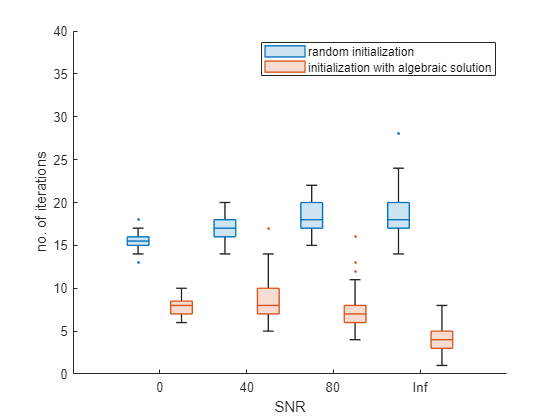

boxchart(categorical(exp_data.SNR),exp_data.iterations,'GroupByColor',exp_data.type,"MarkerStyle",".")
ylabel('no. of iterations')
xlabel('SNR')
%title('iterations required for optimization function(noise on the coeffiecient tensor,\{2,3\} circ)')
legend('random initialization','initialization with algebraic solution')
legend
ylim([0,40])

% exp_data_dupe = exp_data;
% exp_data_dupe.type = exp_data.type';
% exp_data_dupe.iterations = exp_data_dupe.iterations';
% exp_data_dupe.SNR = exp_data_dupe.SNR';
% exp_table = struct2table(exp_data_dupe)
tblstats1 = grpstats(exp_table,["type","SNR"],"median")

tblstats1 = 8×4 table
             type    SNR    GroupCount    median_iterations
             ____    ___    __________    _________________

    0_0       0        0       100               13        
    0_40      0       40       100               14        
    0_80      0       80       100               15        
    0_Inf     0      Inf       100               15        
    1_0       1        0       100                6        
    1_40      1       40       100                5        
    1_80      1       80       100                3        
    1_Inf     1      Inf       100                1        


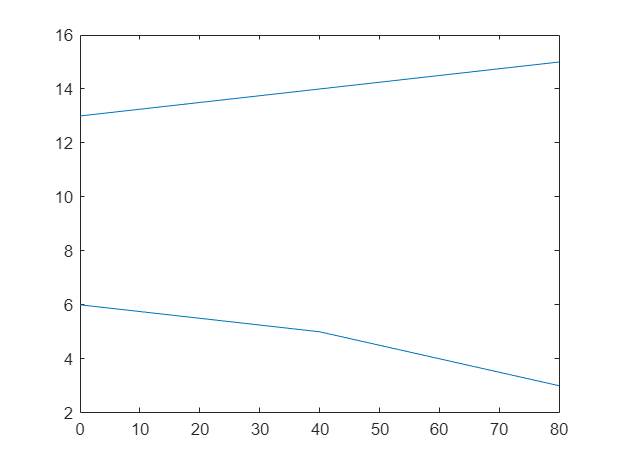

plot(tblstats1.SNR,tblstats1.median_iterations)

SNRS = [0,40,80,Inf];
iters = 100;

%% initialized exp_data %%
init_SNR_iters = [];
rnd_SNR_iters = [];
exp_data.iterations = [];
exp_data.type = [];
exp_data.SNR = ones(1,iters*2)*SNRS(1);
exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*SNRS(2)];
exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*SNRS(3)];
exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*SNRS(4)];
options = struct;
options.TolFun = eps^2;
options.TolX = eps;
options.LargeScale = false;
%% -----------------   %%
for SNR=1:size(SNRS,2)
    init_iterations = [];
    rnd_iterations = [];
    for iter=1:iters
        dim = [20,20,20];
        T = zeros(dim);
        for i = 1:dim(1)
            T(i,:,:) = circulant(randi([-100,100],size(T,2),1),-1);
        end

        x = randi([-100,100],size(T,2),1);
    
        b = tmprod(T,{x.',x.'},[2,3]);
        b_noisy = noisy(b,SNRS(SNR));
        T_noisy = noisy(T,SNRS(SNR));
        T_noisy_dup  = T_noisy;


        F = 1/sqrt(dim(2))*dftmtx(dim(2));
        F_list = {F,F};
        omega = tmprod(T_noisy_dup,F_list,[2,3]);
        T_noisy_dup = zeros(size(omega));

        for k = 1:size(T,1)
            T_noisy_dup(k,:,:) = diag(diag(squeeze(omega(k,:,:))));
        end

        y = solve_part_diag(T_noisy_dup,b_noisy);
        xest = conj(F)\y;   

     
        U0 = {xest,xest};
        [U,output] = lscpd_nls(T_noisy,b_noisy,U0,options);
        init_iterations = [init_iterations,output.iterations];

        %%collecting data
        exp_data.iterations = [exp_data.iterations,output.iterations];
        exp_data.type = [exp_data.type,1];
        %%--------------%%

        U0 = cpd_rnd(dim(2:3),1);
        [U2,output2] = lscpd_nls(T_noisy,b_noisy,U0,options);

        %%collecting data
        rnd_iterations= [rnd_iterations,output2.iterations];
        exp_data.iterations = [exp_data.iterations,output2.iterations];
        exp_data.type = [exp_data.type,0];
        %%--------------%%
    end
    init_SNR_iters = [init_SNR_iters;init_iterations];
    rnd_SNR_iters = [rnd_SNR_iters;rnd_iterations];
end

Experiments for circulant hankel structure

SNRS = [0,10,20,30];
iters = 100;

%% initialized exp_data %%
init_SNR_iters = [];
rnd_SNR_iters = [];
exp_data.iterations = [];
exp_data.type = [];
exp_data.SNR = ones(1,iters*2)*0;
exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*10];
exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*20];
exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*30];
%% -----------------   %%
for SNR=1:size(SNRS,2)
    init_iterations = [];
    rnd_iterations = [];
    for iter=1:iters
        dim = [20,20,20];
        T = zeros(dim);
        for i = 1:dim(1)
            T(i,:,:) = circulant(randn(dim(2),1),-1);
        end

        x = randn(dim(2),1);
    
        b = tmprod(T,{x.',x.'},[2,3]);
        b_noisy = noisy(b,SNRS(SNR));
        T_noisy = noisy(T,SNRS(SNR));
        T_noisy_dup  = T_noisy;


        F = 1/sqrt(dim(2))*dftmtx(dim(2));
        F_list = {F,F};
        omega = tmprod(T_noisy_dup,F_list,[2,3]);

        for k = 1:size(T,3)
            filt = zeros(dim(1),dim(2));
            filt(k,k) = 1;
            omega(:,:,k) = omega(:,:,k)*filt;
        end

        y = solve_part_diag(omega,b_noisy);
        xest = conj(F)\y;   
     
        U0 = {xest,xest};
        [U,output] = lscpd_nls(T_noisy,b_noisy,U0);
        init_iterations = [init_iterations,output.iterations];

        %%collecting data
        exp_data.iterations = [exp_data.iterations,output.iterations];
        exp_data.type = [exp_data.type,1];
        %%--------------%%

        U0 = cpd_rnd(dim(2:3),1);
        [U2,output2] = lscpd_nls(T_noisy,b_noisy,U0);

        %%collecting data
        rnd_iterations= [rnd_iterations,output2.iterations];
        exp_data.iterations = [exp_data.iterations,output2.iterations];
        exp_data.type = [exp_data.type,0];
        %%--------------%%
    end
    init_SNR_iters = [init_SNR_iters;init_iterations];
    rnd_SNR_iters = [rnd_SNR_iters;rnd_iterations];
end

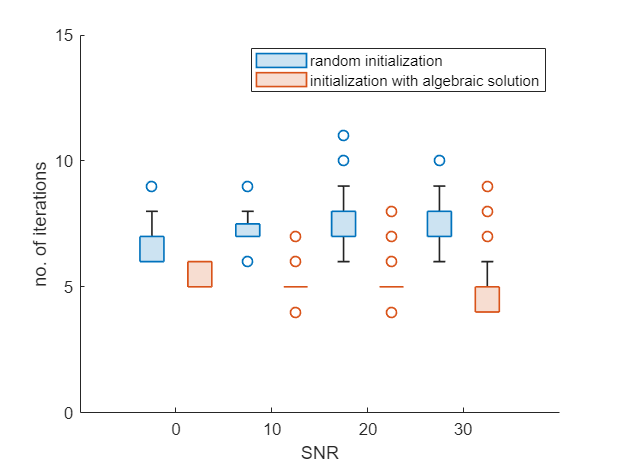

boxchart(categorical(exp_data.SNR),exp_data.iterations,'GroupByColor',exp_data.type)
ylabel('no. of iterations')
xlabel('SNR')
%title('iterations required for optimization function(noise on the coeffiecient tensor,\{2,3\} circ and right hand side b)')
legend('random initialization','initialization with algebraic solution')
legend
ylim([0,15])